# Constraints Handling and Receding Horizon

close all
clear 
clc

As we can easily imagine, our control input can't assume all possible values, due, for example, to physical limitations of the actuator. So, we must define a procedure that works when our control input u(t) is constrained (e.g. saturation constraint).

## Finite horizon unconstrained control

We start by a simple case in which we don't have constraints. As the title suggests, differently from LQR we are interested in a finite horizon optimization (i.e. we seeks best input u(t) just for few iterations). 

**Note: **

- math passages are not reported

- I suppose that you already know some theory about it 

#### New system matrices

Just a reminder (they are on the formulary)

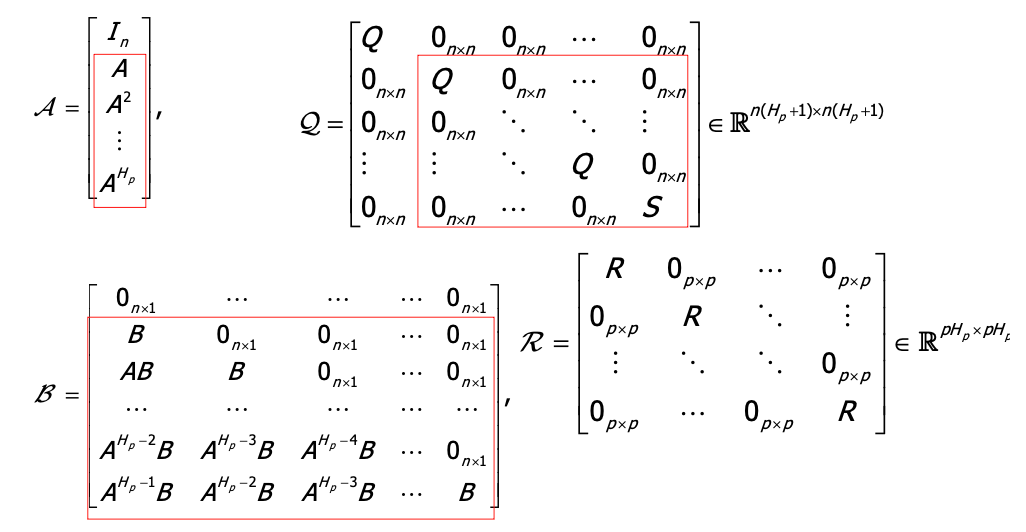

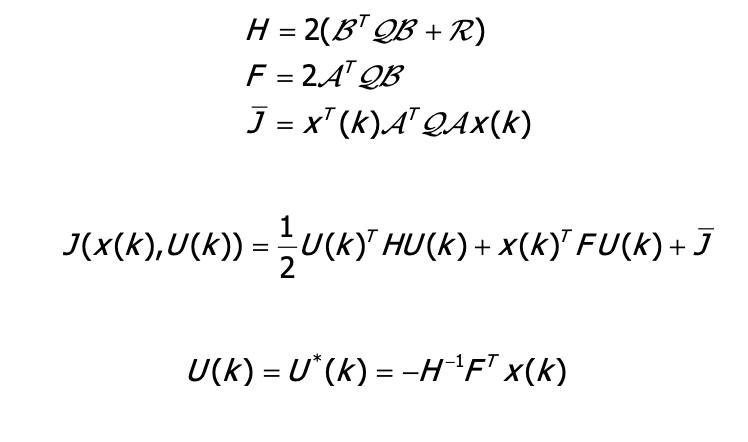

Basically the flowchart is:

- (data)

- compute calligraphic matrices

- compute H and F matrices

- compute U(k) and corresponding state X(k)

Let's go directly to an exercise:

## Exercise on unconstrained ...

#### Lab 5, problem 1

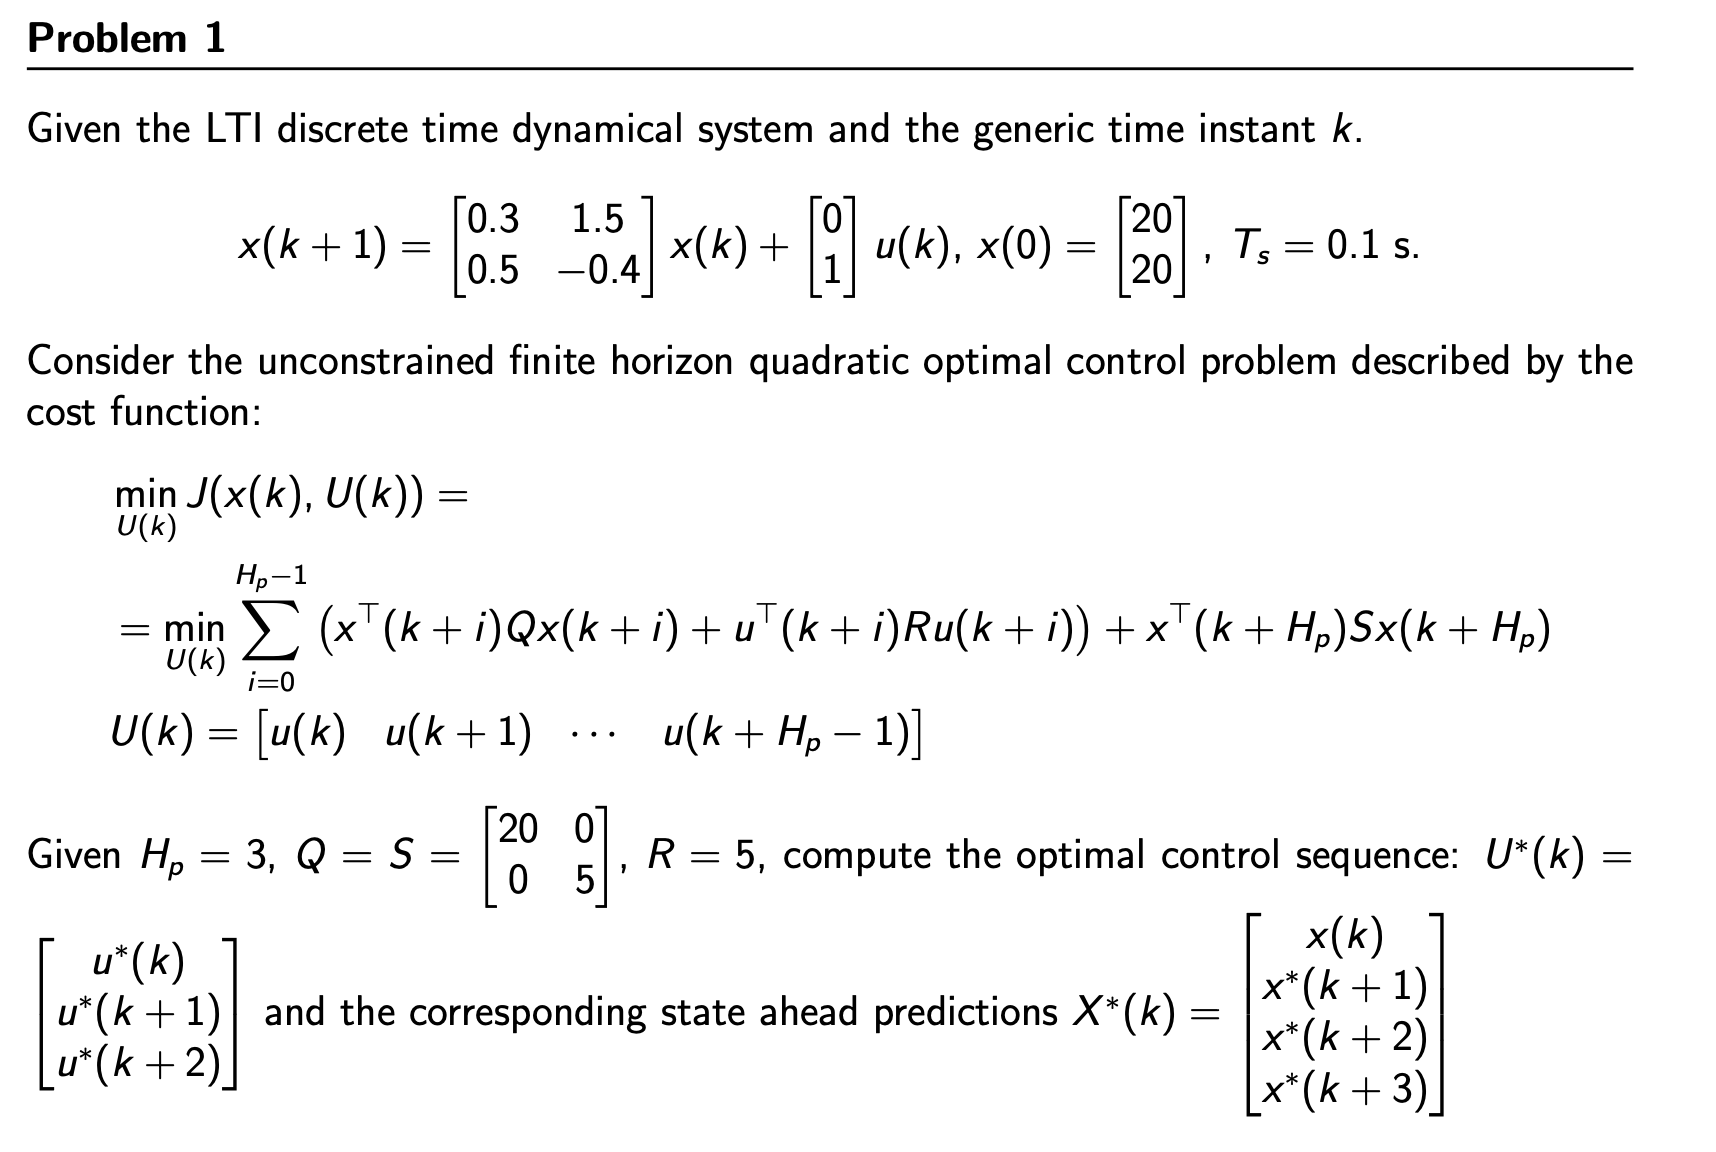

A = [0.3 1.5; 0.5 -0.4];
B = [0; 1];
x0 = [20;20];
Ts = 0.1;
Hp = 3;
Q = [20 0; 0 5];
S = Q;
R = 5;

% build cal matrices
n = size(A, 1); 
p = size(B, 2); 
A_cal = [A;A^2;A^3];
B_cal = [[B zeros(n,1) zeros(n,1)]; [A*B B zeros(n,1)]; [A^2*B A*B B]];
Q_cal = blkdiag(Q,Q,Q);
R_cal = blkdiag(R,R,R);

% build other matrices
H = 2*(B_cal'*Q_cal*B_cal + R_cal);
F = 2*A_cal'*Q_cal*B_cal;

x_k = x0;
% compute U(k)
U = -H\(F'*x_k)

U =    -7.5261
  -18.7716
   -0.3400



% compute corresponding state values
X = A_cal*x_k+B_cal*U

X =    36.0000
   -5.5261
    2.5109
    1.4388
    2.9115
    0.3400


## Finite horizon constrained control 

We now include constraints in our analysis

Long story short: these are the constraints

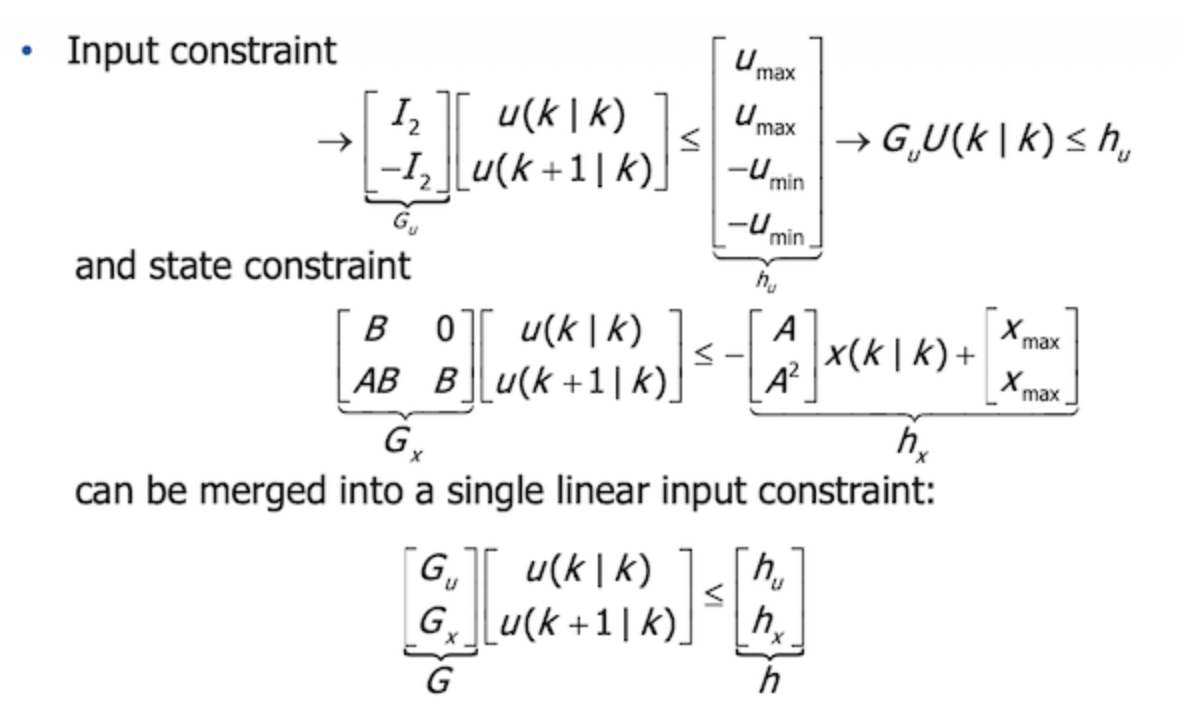

**WARNING!!! These constraint inequalities ARE NOT on the formulary!!!**

**Note: **exercise is exactly the same!!!!! but:

- we have to compute matrices G and h

- U(k) is computed in a different way ->  with quadprog

So let's jump to the next ex. (we now include just input constraints)

## Exercise on constrained input finite ...

#### Lab 5, problem 2

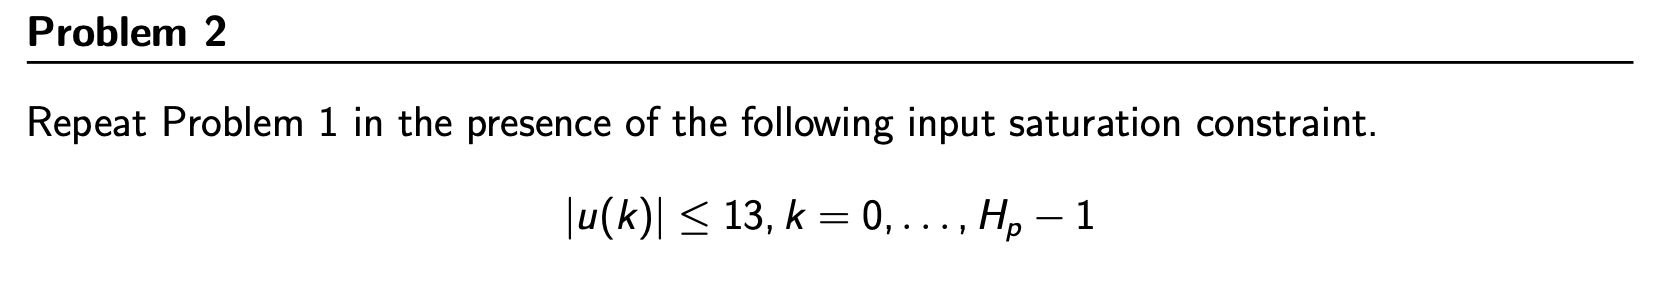

**Note before starting:**

we can see that our previous optimal control input exceeds boundaries!!! After this little ex we'll obtain an input that satisfies our constraints.

% include input constraints
u_max = 13;
h = u_max*ones(2*Hp,1);
G = [eye(Hp); -eye(Hp)];

% force H symmetry 
H = (H+H')/2;

% compute optimized input
U = quadprog(H,x_k'*F,G,h)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -6.7928
  -13.0000
    0.4807



% find state prediction associated
X_k=A_cal*x_k+B_cal*U

X_k =    36.0000
   -4.7928
    3.6109
    6.9171
   11.4589
   -0.4807


## Receding Horizon

Previously, we saw how to compute the optimal control input over a time horizon without any feedback => this makes weak the application of such a constrained finite horizon optimal control strategy in the presence of disturbances, uncertainty  and measurement errors => we introduce feedback by **solving the considered constrained finite horizon optimal control at each time instant k -> Receding Horizon Principle**

**Flowchart:**

- start: x_k

- for (number_of_steps) 

-     compute optimal input sequence U(k) (with quadprog)

-     take just the first element U(1)

-     compute corresponding state x(k+1) = ... with U(1)

-     update initial state x_k

- repeat

We'll do ex 3 and 4 from lab 6 in order to apply RH principle and include also state constraints

## Exercise on RH principle

#### Lab 6, problem 3 & 4

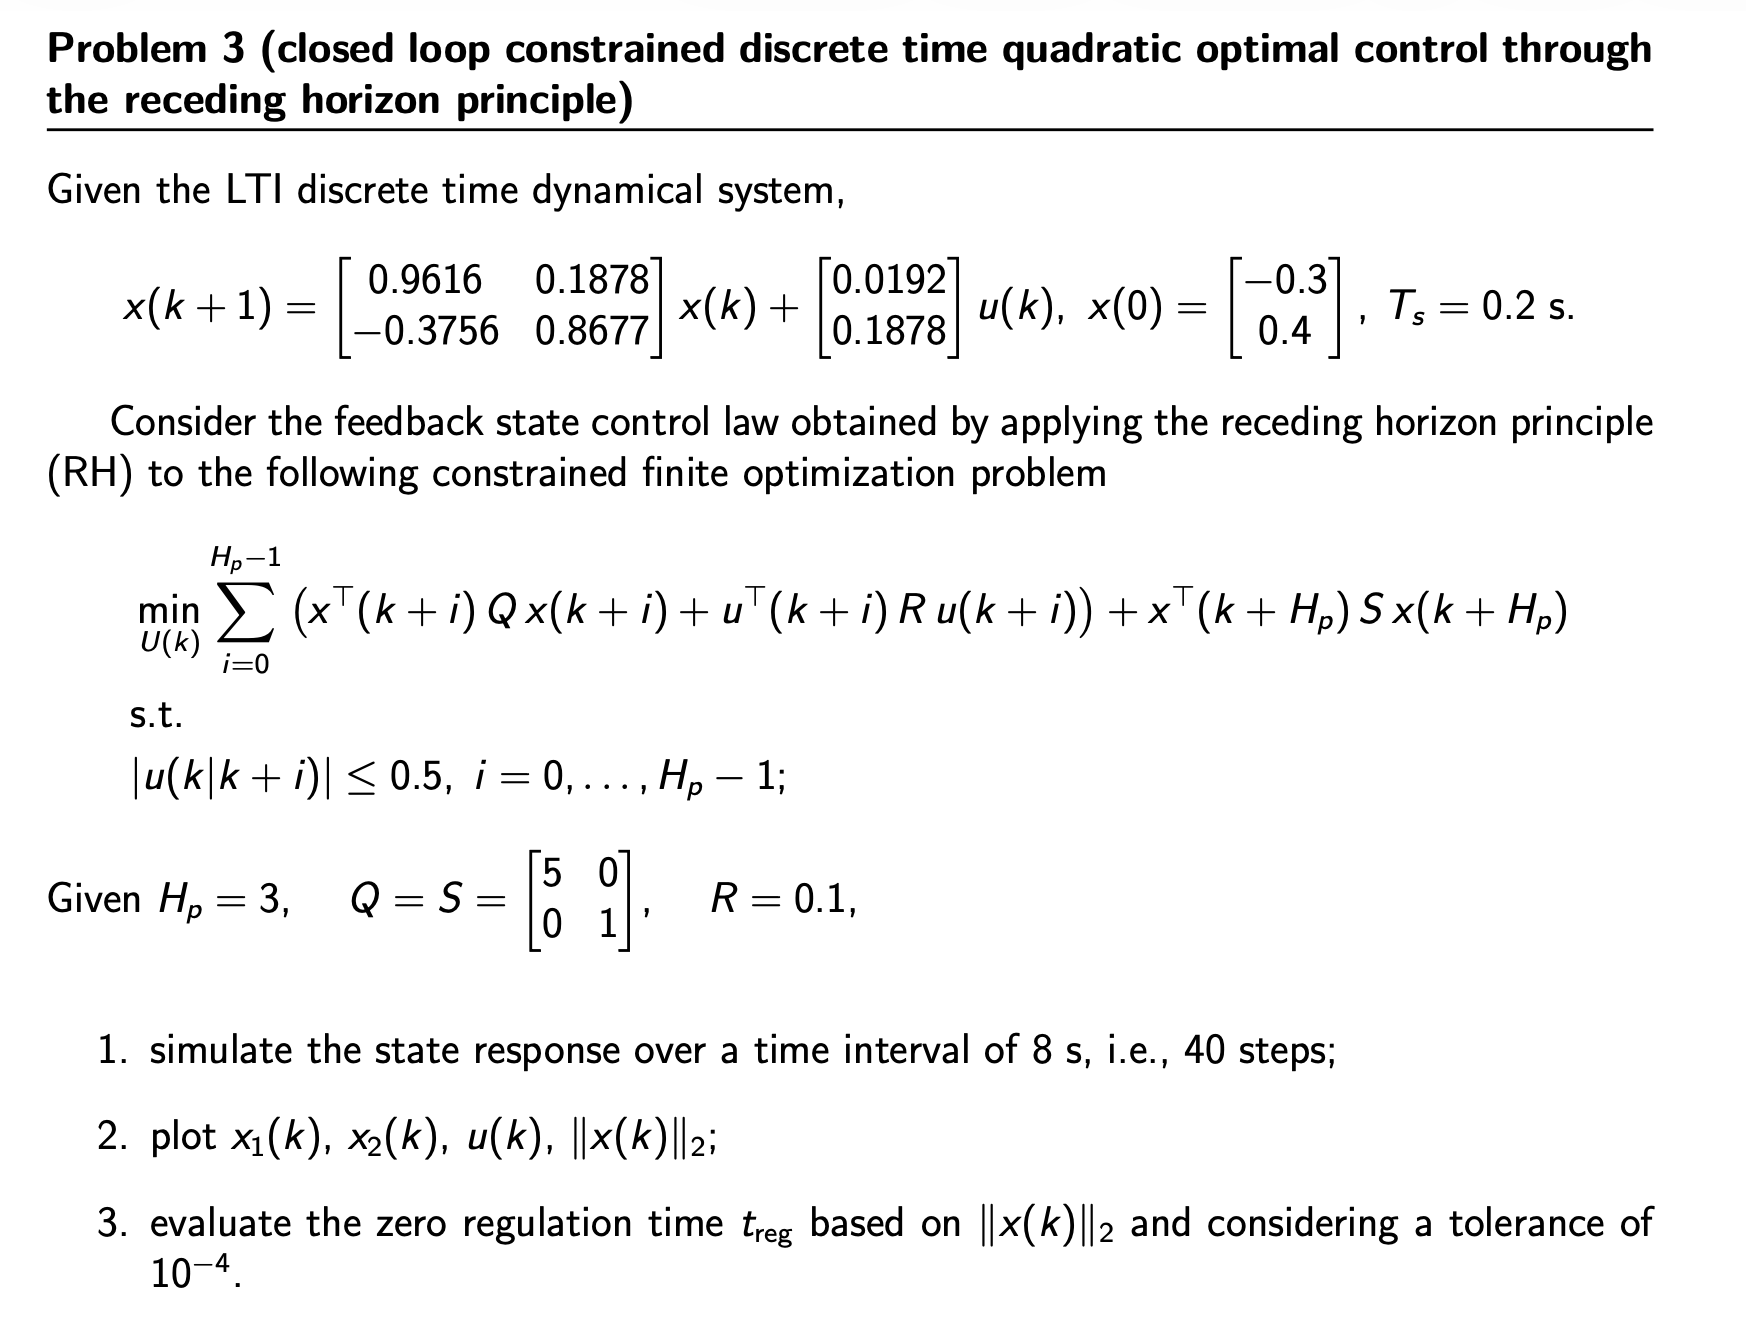

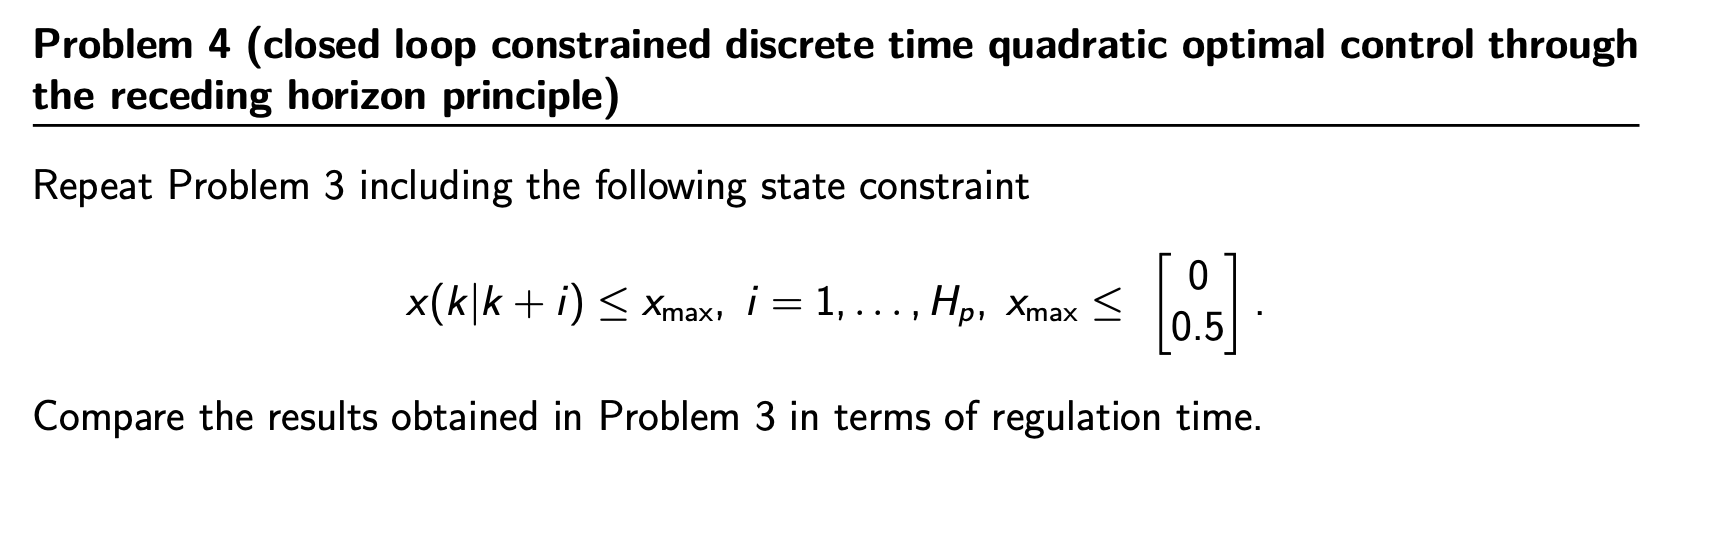

Let's start with just input constraint

clear

A = [0.9616 0.1878; -0.3756 0.8677];
B = [0.0192; 0.1878];
x0 = [-0.3; 0.4];
Ts = 0.2;
x_k = x0;

u_sat = 0.5;
Hp = 3;
Q = [5 0; 0 1];
S = Q;
R = 0.1;
t_int = 8; 
steps = 40;
n = size(A,1);
p = size(B,2);

% cal matrices
A_cal = [A;A^2;A^3];
B_cal = [[B zeros(n,1) zeros(n,1)]; [A*B B zeros(n,1)]; [A^2*B A*B B]];
Q_cal = blkdiag(Q,Q,Q);
R_cal = blkdiag(R,R,R);

H = 2*(B_cal'*Q_cal*B_cal + R_cal);
H = (H+H')/2; % symm
F = 2*A_cal'*Q_cal*B_cal;

% for input constraints, we can define before the loop our inequality
% matrices

Gu = [eye(Hp); -eye(Hp)];
hu = u_sat*ones(2*Hp,1);

x_traj(:,1) = x_k;

for kk=1:steps
    
    % compute optimal U
    U = quadprog(H,x_k'*F,Gu,hu);

    % compute state traj
    x_traj(:,kk+1) = A*x_k + B*U(1); % NOTE: IT'S A AND B, NOT A_CAL B_CAL!!

    % update initial state and store U value
    x_k = x_traj(:, end);
    u_traj(kk) = U(1);

end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

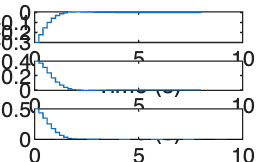


figure
subplot(311)
stairs(0:Ts:steps*Ts, x_traj(1,:))
xlabel('Time (s)')
ylabel('First State Trajectory')

subplot(312)
stairs(0:Ts:steps*Ts, x_traj(2,:))
xlabel('Time (s)')
ylabel('Second State Trajectory')

subplot(313)
stairs(0:Ts:steps*Ts, sqrt(x_traj(1,:).^2 + x_traj(2,:).^2))
xlabel('Time (s)')
ylabel('State Norm')
yline(1e-4, 'k--');

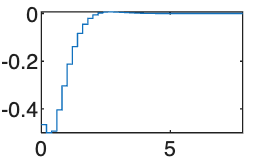


figure
stairs(0:Ts:(steps-1)*Ts, u_traj)

Now let's include state constraints

clear x_traj u_traj
x_k = x0;


differently from input constraints, these constraints depend on current x_k => we have to update it at every loop iteration

**Note: **Gx coincides with B_cal and hx coincides with A_cal

Gx = B_cal;
x_max = [0; 0.5];

% start again the cycle
for kk=1:steps
   
    hx = - A_cal*x_k + repmat(x_max, Hp, 1); % repmat replicates the vector x_max according to a matrix with 3 rows (=Hp) and 1 columns
    
    % concatenate constraints
    G = [Gu; Gx];
    h = [hu; hx];

    % compute optimal U
    U = quadprog(H,x_k'*F,G,h);

    % compute state traj
    x_traj(:,kk+1) = A*x_k + B*U(1); % NOTE: IT'S A AND B, NOT A_CAL B_CAL!!

    % update initial state and store U value
    x_k = x_traj(:, end);
    u_traj(kk) = U(1);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

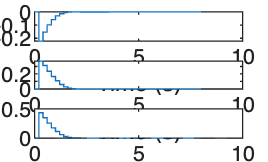


figure
subplot(311)
stairs(0:Ts:steps*Ts, x_traj(1,:))
xlabel('Time (s)')
ylabel('First State Trajectory')

subplot(312)
stairs(0:Ts:steps*Ts, x_traj(2,:))
xlabel('Time (s)')
ylabel('Second State Trajectory')

subplot(313)
stairs(0:Ts:steps*Ts, sqrt(x_traj(1,:).^2 + x_traj(2,:).^2))
xlabel('Time (s)')
ylabel('State Norm')
yline(1e-4, 'k--');

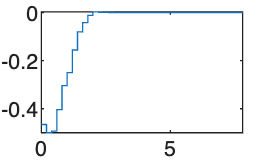


figure
stairs(0:Ts:(steps-1)*Ts, u_traj)